y = [1.8, 4.9, 7.5, 10.2, 11.5, 13.3, 14.1, 13.2, 11.8, 11.7]/100;
x = [1,2,3,4,5,6,7,8,9,10];
xn = randsrc(1000000,1,[x; y]);
pd = fitdist(xn,'Kernel','Kernel','Epanechnikov');
x_values = 0:1:10

x_values =      0     1     2     3     4     5     6     7     8     9    10


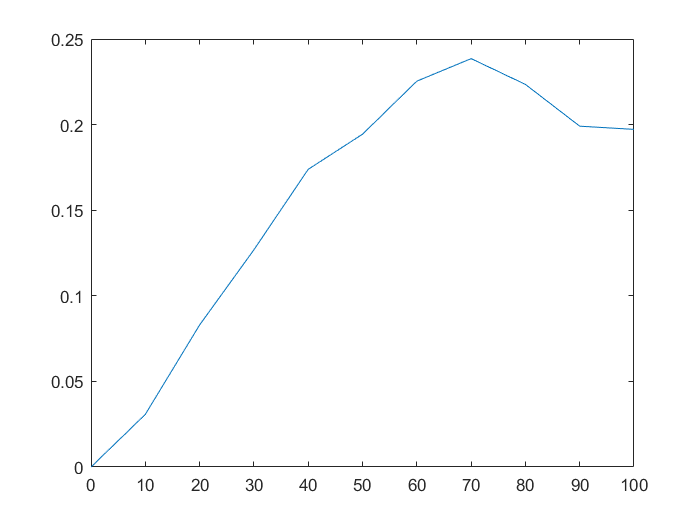

yi = pdf(pd,x_values);
plot(x_values * 10,yi);

data = pd.random(1,100000) * 10;
eval('data')

data =    50.8181   60.9589   76.8765   59.6283   63.1110   38.2321   48.7590   71.7952   57.7279   49.8744   47.7696   42.9477   78.8556   58.4109   89.8205   69.5632   46.4831   47.8941   72.0956   80.2323   68.4389   71.5914   71.1819   41.2380  103.6521   40.6037   49.9387   70.0423   71.3282   56.5466   22.2352   69.5150   39.2811   42.3792   62.5311  103.1937   30.6730   83.8939   58.3798   79.4165   70.8528   91.6798   97.2712   46.6967   50.2695   62.1732   49.6585   27.9117   58.9344   78.0902


eval('pd')

pd =   KernelDistribution

    Kernel = epanechnikov
    Bandwidth = 0.198169
    Support = unbounded


csvwrite('充电起始SOC.txt', data)